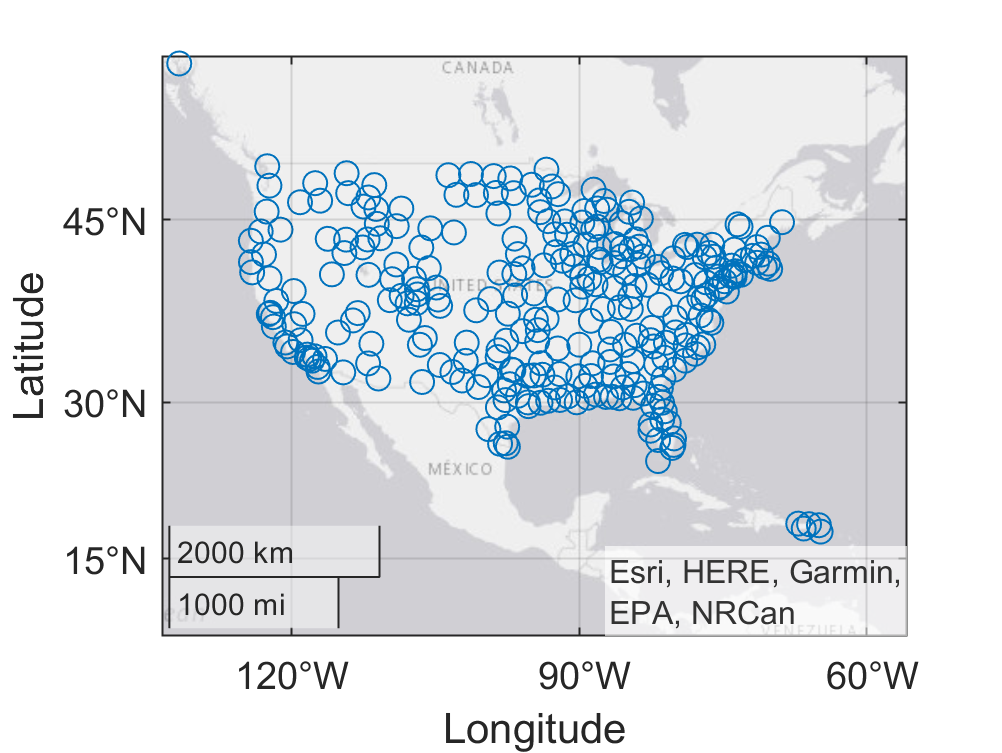

geoscatter(airports.LATITUDE,airports.LONGITUDE)
geolimits([7.1 55.8],[-132.8 -56.5])

flights = importFlightsData("flightsFeb.csv")

flights = 429191×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

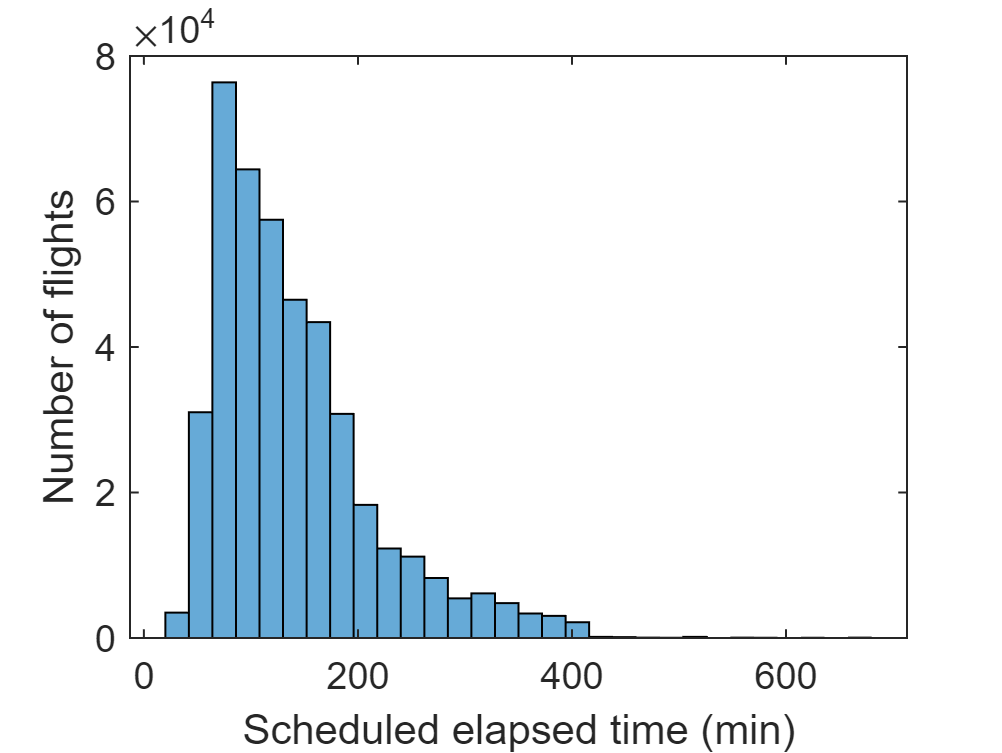

histogram(flights.SCHEDULED_ELAPSED_TIME,30)
xlabel("Scheduled elapsed time (min)")
ylabel("Number of flights")

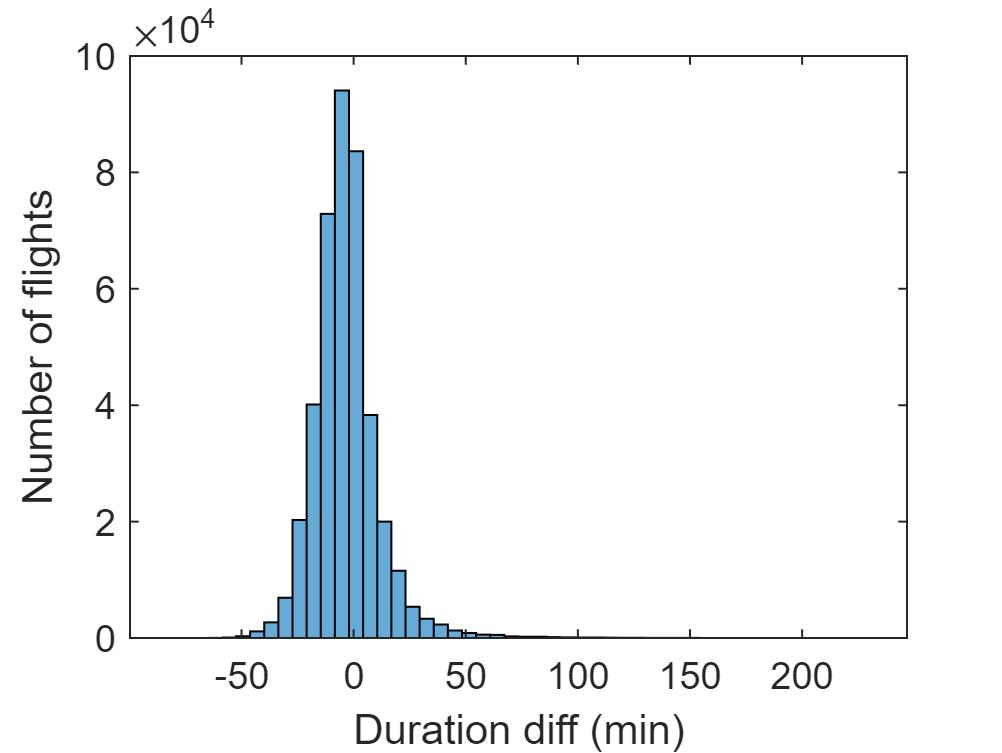

flights.DURATION_DIFF = flights.ACTUAL_ELAPSED_TIME-flights.SCHEDULED_ELAPSED_TIME;
histogram(flights.DURATION_DIFF,50)
xlabel("Duration diff (min)")
ylabel("Number of flights")

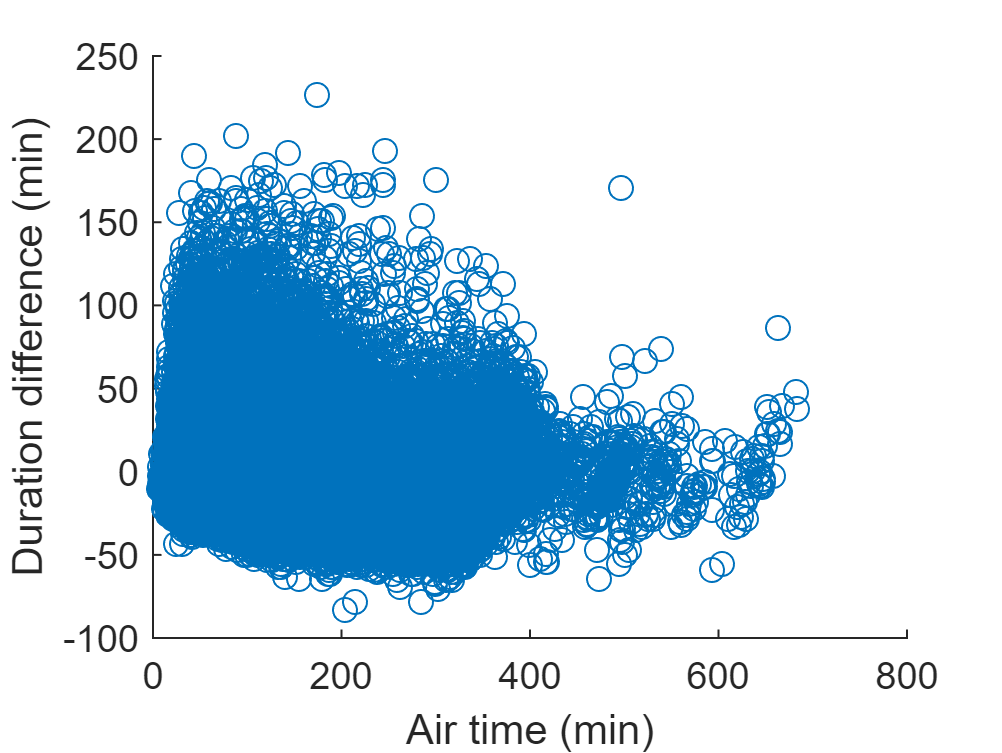

scatter(flights.AIR_TIME,flights.DURATION_DIFF)
xlabel("Air time (min)")
ylabel("Duration difference (min)")

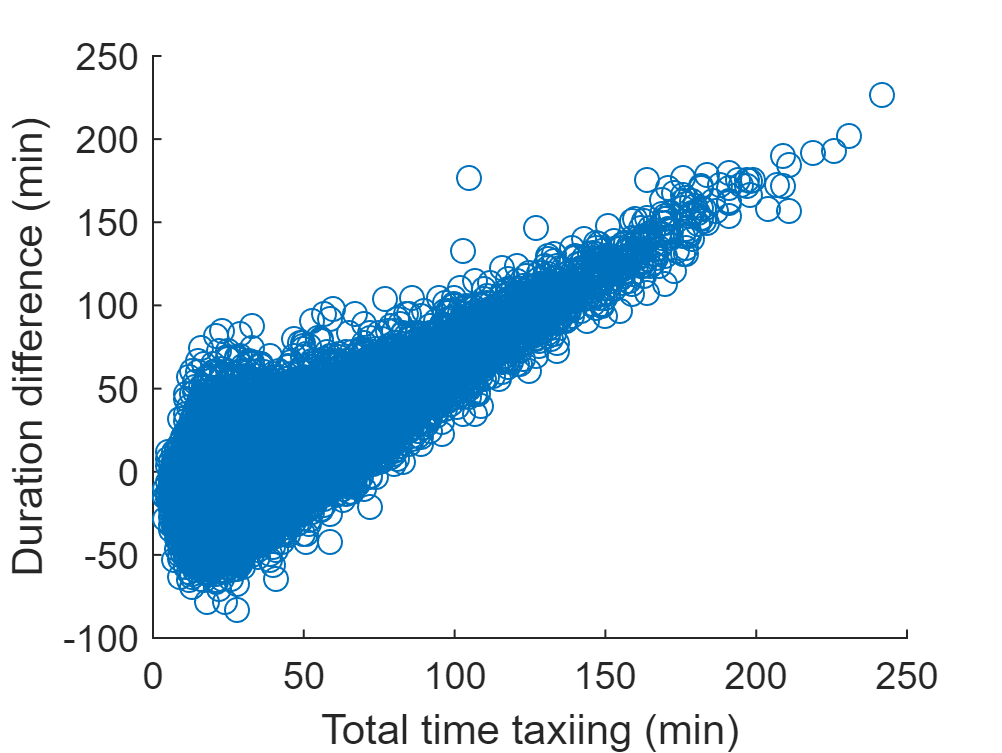

flights.TAXI_TOTAL = flights.TAXI_OUT+flights.TAXI_IN;
scatter(flights.TAXI_TOTAL,flights.DURATION_DIFF);
xlabel('Total time taxiing (min)')
ylabel('Duration difference (min)')

corr(flights.TAXI_TOTAL,flights.DURATION_DIFF,"rows","complete")

ans = 0.6976

flights(135:140,:)

ans = 6×22 table
              AIRLINE              TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED    DURATION_DIFF    TAXI_TOTAL
    ___________________________    ___________    _____________    ______    ___________    _______________________

flightsCan = flights(flights.CANCELLED == 1,:);
numberCancelled = height(flightsCan)

numberCancelled = 20517

percentCancelled = height(flightsCan)/height(flights) *100

percentCancelled = 4.7804

cancelledsummary = groupsummary(flightsCan,"ORIGIN")

cancelledsummary = 292×2 table
    ORIGIN    GroupCount
    ______    __________

     ABE          11    
     ABI          32    
     ABQ          53    
     ABY           2    
     ACT          24    
     ACV           6    
     ACY           4    
     ADQ           4    
     AEX          21    
     AGS           3    
     ALB          28    
     ALO           7    
     AMA          47    
     ANC          20    
     APN           5    
     ASE          83    


sortrows(cancelledsummary,"GroupCount","descend")

ans = 292×2 table
    ORIGIN    GroupCount
    ______    __________

     DFW         2000   
     ORD         1699   
     BOS         1145   
     LGA         1068   
     ATL          932   
     EWR          616   
     DCA          561   
     JFK          483   
     CLT          469   
     MDW          461   
     BNA          421   
     DEN          401   
     DTW          375   
     SFO          348   
     BWI          335   
     LAX          327   


cancelledAirport = flightsCan(flightsCan.ORIGIN == "BOS",:);
cancelledAirportSummary = groupsummary(cancelledAirport,'SCHEDULED_DEPARTURE_TIME','day')

cancelledAirportSummary = 26×2 table
    day_SCHEDULED_DEPARTURE_TIME    GroupCount
    ____________________________    __________

            01-Feb-2015                 15    
            02-Feb-2015                286    
            03-Feb-2015                 77    
            05-Feb-2015                 18    
            06-Feb-2015                  2    
            08-Feb-2015                 23    
            09-Feb-2015                265    
            10-Feb-2015                 65    
            11-Feb-2015                  1    
            12-Feb-2015                  2    
            13-Feb-2015                  3    
            14-Feb-2015                  5    
            15-Feb-2015                228    
            16-Feb-2015                 54    
            17-Feb-2015                 30    
            18-Feb-2015                  2    


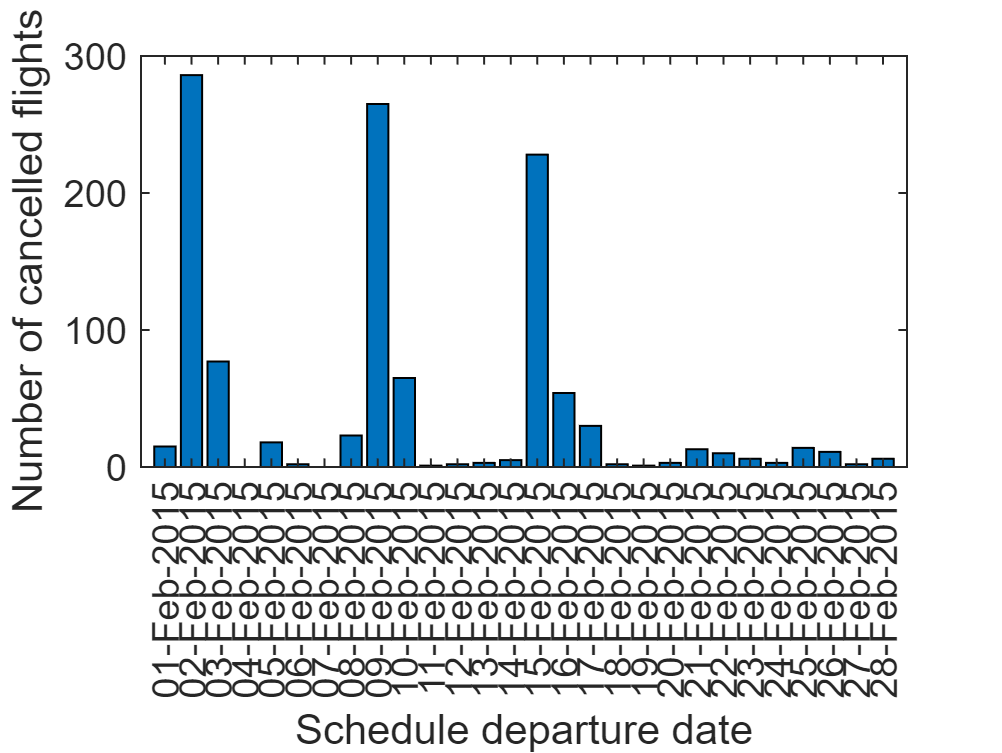

bar(cancelledAirportSummary.day_SCHEDULED_DEPARTURE_TIME,cancelledAirportSummary.GroupCount)
xlabel("Schedule departure date")
ylabel("Number of cancelled flights")